**Configuration Space Computation for a Two-Link Planar Robot Arm**

Configuration Space, commonly abbreviated as **C-Space**, is a mathematical representation of all possible configurations of a robotic system. Each configuration corresponds to a unique set of values for the robot's degrees of freedom (DOFs), such as joint angles or positions.

In robotics, C-Space helps to analyze motion planning by identifying collision-free and collision-prone regions for the robot.

**Configuration:**

- A configuration specifies the exact pose of a robot in the environment.

- For a robot with nnn degrees of freedom (DOFs), the configuration is a point in an nnn-dimensional space: $\mathbf{q} = (q_1, q_2, \dots, q_n)$ where $q_i$� represents the i-th DOF (e.g., joint angle or position).

**C-Space Representation:**

- **Dimensionality:** The dimensionality of the C-Space equals the number of DOFs of the robot. For example:

- A 2-link planar robot arm has two DOFs $$\vartheta_1, \vartheta_2$$  so its C-Space is 2-dimensional.

A free-flying rigid body in 3D space has 6 DOFs (3 translations and 3 rotations), so its C-Space is 6-dimensional.

- **Collision-Free Space (Free C-Space):** The set of configurations where the robot avoids collisions with obstacles.

- **Collision Space:** The set of configurations where the robot collides with obstacles or itself.

**C-Space Obstacles:**

- Physical obstacles in the workspace are transformed into regions in C-Space where the robot cannot exist without collision.

- The shape and size of obstacles in C-Space depend on the geometry of the robot and the obstacles.

**Objective:**

The goal of this assignment is to compute and visualize the configuration space (C-space) of a two-link planar robotic arm in a workspace containing polygonal obstacles. Additionally, you will visualize the robot's configuration for randomly selected collision-free joint states.

**Instructions:**

**Environment Setup:**

- Define the workspace limits.

- Define multiple polygonal obstacles in the workspace. For example:

- Obstacle 1: A square defined by vertices `[0.5, 0.5]`, `[0.5, 1]`, `[1, 1]`, `[1, 0.5]`.

- Obstacle 2: A square defined by vertices `[-1, -1]`, `[-1, -0.5]`, `[-0.5, -0.5]`, `[-0.5, -1]`.

**Robot Parameters:**

- Define a two-link planar robot arm with:

- Link lengths: a`1 = 1` and a`2 = 1`.

- Joint angles: $\vartheta_1,\vartheta_2$,

**Collision Detection:**

- Implement functions to:

- Check if a line segment (robot link) collides with a polygonal obstacle.

- Check if two line segments intersect.

**Configuration Space Computation:**

- Discretize $\vartheta_1,\vartheta_2$ � into 100 values each.

- For every pair of $\vartheta_1,\vartheta_2$:

- Calculate the positions of the robot's joints.

- Determine if either link of the robot collides with any obstacle.

- Create a binary map of the C-space where:

- `0` represents a collision-free configuration.

- `1` represents a configuration in collision.

**Visualizations:**

- **C-space Map:**

- Plot the C-space as a 2D image with $\vartheta_1$ � on the x-axis and $\vartheta_2$� on the y-axis.

- Use white to indicate free space and black to indicate collisions.

- **Workspace and Robot Visualization:**

- Plot the workspace, obstacles, and the robot for 10 random collision-free configurations.

- Highlight the robot's links and end-effector position.

- **Code Execution:**

- Run the MATLAB script to generate:

- The C-space map.

- The workspace visualization showing the robot in random collision-free configurations.

**Submission Requirements:**

- Submit the MATLAB script with clear comments explaining each section.

- Include screenshots of:

- The C-space map.

- The workspace visualization with the robot and obstacles.

- Answer the following questions:

- What challenges did you face in implementing collision detection?

- How does the resolution of the C-space discretization affect the results?

%2-DOF Robot Configuration Space Analysis
% Advanced visualization and optimization included
clear;

%% 1. ROBOT PARAMETERS AND KINEMATICS
fprintf(' _2-DOF Robot C-Space Analysis_ \n');

 _2-DOF Robot C-Space Analysis_ 



% Robot parameters
a1 = 1; % Length of link 1 (m)
a2 = 1; % Length of link 2 (m)

% Forward kinematics function (vectorized for efficiency)
fkine = @(q1, q2) [
    zeros(size(q1)), zeros(size(q1));                    % Base (0,0)
    a1*cos(q1), a1*sin(q1);                              % Elbow joint
    a1*cos(q1) + a2*cos(q1+q2), a1*sin(q1) + a2*sin(q1+q2)  % End-effector
];


% 2. WORKSPACE ENVIRONMENT SETUP
workspace_limits = [-2, 2, -2, 2]; % [xmin, xmax, ymin, ymax]

% Defining polygonal obstacles (counter-clockwise order)
obs1_vertices = [0.5, 0.5; 0.5, 1; 1, 1; 1, 0.5];     % Square obstacle 1
obs2_vertices = [-1, -1; -1, -0.5; -0.5, -0.5; -0.5, -1]; % Square obstacle 2

% Store obstacles in cell array
obstacles = {obs1_vertices, obs2_vertices};

fprintf('Workspace initialized with %d obstacles\n', length(obstacles));

Workspace initialized with 2 obstacles




% 3. COLLISION DETECTION FUNCTIONS
% Helper function for 2D cross product (scalar)
function result = cross2d(a, b)
    result = a(1)*b(2) - a(2)*b(1);
end

% Function to check if two line segments intersect somewhere
function intersect = segmentIntersection(p1, p2, q1, q2)
    % p1, p2: endpoints of first segment
    % q1, q2: endpoints of second segment
    
    % Vector representation
    r = p2 - p1;
    s = q2 - q1;
    
    % Cross products
    rxs = cross2d(r, s);
    
    % Check if segments are parallel (or collinear)
    if abs(rxs) < 1e-10
        intersect = false;
        return;
    end
    
    % Compute intersection parameters using Cramer's rule
    t = cross2d(q1 - p1, s) / rxs;
    u = cross2d(q1 - p1, r) / rxs;
    
    % Check if intersection point lies on both segments
    intersect = (t >= 0 && t <= 1 && u >= 0 && u <= 1);
end

% Function to check if a line segment intersects with a polygon
function collision = segmentPolygonCollision(seg_start, seg_end, polygon)
    % Check if line segment intersects any edge of the polygon
    n = size(polygon, 1);
    
    % Quick bounding box test for efficiency
    seg_min = min([seg_start; seg_end]);
    seg_max = max([seg_start; seg_end]);
    poly_min = min(polygon);
    poly_max = max(polygon);
    
    % Axis-aligned bounding box test (early exit)
    if seg_max(1) < poly_min(1) || seg_min(1) > poly_max(1) || ...
       seg_max(2) < poly_min(2) || seg_min(2) > poly_max(2)
        collision = false;
        return;
    end
    
    % Check segment against each polygon edge
    for i = 1:n
        j = mod(i, n) + 1; % Next vertex (wrapping around)
        if segmentIntersection(seg_start, seg_end, polygon(i,:), polygon(j,:))
            collision = true;
            return;
        end
    end
    collision = false;
end

% 4. CONFIGURATION SPACE COMPUTATION (WITH OPTIMIZATION)
N = 100; % Resolution for discretization
theta_range = linspace(-pi, pi, N); % Joint angle range [-π, π]

% Initialize C-space map as logical array (memory efficient)
C_Map = false(N, N); % false = free, true = collision

% Pre-compute all joint angle combinations
[Q1, Q2] = meshgrid(theta_range, theta_range);
Q1_flat = Q1(:);
Q2_flat = Q2(:);
total_configs = numel(Q1);

% Create waitbar for progress indication
fprintf('Computing C-space with resolution %dx%d...\n', N, N);

Computing C-space with resolution 100x100...


tic;




% Iterate through all joint configurations
for idx = 1:total_configs
    q1 = Q1_flat(idx);
    q2 = Q2_flat(idx);
    
    % Forward kinematics
    p0 = [0, 0];
    p1 = [a1*cos(q1), a1*sin(q1)];
    p2 = p1 + [a2*cos(q1+q2), a2*sin(q1+q2)];
    
    % Collision detection with early exit
    collision_detected = false;
    for k = 1:length(obstacles)
        % Check both robot links against the current obstacle
        if segmentPolygonCollision(p0, p1, obstacles{k}) || ...
           segmentPolygonCollision(p1, p2, obstacles{k})
            collision_detected = true;
            break; % Exit early if collision detected
        end
    end
    
    % Mark collision in C-space map
    if collision_detected
        [i, j] = ind2sub([N, N], idx);
        C_Map(i, j) = true;
    end
    
    % Update progress bar every 1000 iterations
    if mod(idx, 1000) == 0
        %waitbar(idx/total_configs, h_wait, ...
            fprintf('Progress: %.1f%%', idx/total_configs*100);
    end
end

Progress: 10.0%Progress: 20.0%Progress: 30.0%Progress: 40.0%Progress: 50.0%Progress: 60.0%Progress: 70.0%Progress: 80.0%Progress: 90.0%Progress: 100.0%


%close(h_wait);
computation_time = toc;

% Calculate statistics
free_count = sum(~C_Map(:));
collision_count = sum(C_Map(:));
free_percentage = free_count / total_configs * 100;

fprintf('C-space computation completed in %.2f seconds\n', computation_time);

C-space computation completed in 0.50 seconds


fprintf('Statistics:\n');

Statistics:


fprintf('  Total configurations: %d\n', total_configs);

  Total configurations: 10000


fprintf('  Free configurations: %d (%.1f%%)\n', free_count, free_percentage);

  Free configurations: 7292 (72.9%)


fprintf('  Collision configurations: %d (%.1f%%)\n', ...
    collision_count, 100-free_percentage);

  Collision configurations: 2708 (27.1%)



%% 5. ENHANCED C-SPACE VISUALIZATION (PROFESSIONAL)
figure('Position', [50, 50, 1400, 600], 'Name', 'C-Space Analysis', ...
    'Color', 'white');

% Custom colormap for better visualization
free_color = [0.95, 0.95, 0.95];  % Light gray for free
collision_color = [0.5, 0, 0];     % Dark red for collision
custom_cmap = [free_color; collision_color];

%  Subplot 1: C-space with contour lines and statistics 
subplot(1, 3, 1);
imagesc(theta_range, theta_range, double(C_Map'));
colormap(custom_cmap);
caxis([0, 1]);
hold on;

% Add contour lines for C-space boundaries
contour(theta_range, theta_range, double(C_Map'), [0.5, 0.5], ...
    'b-', 'LineWidth', 1.5);

% Highlight joint limits
plot([-pi, pi], [-pi, -pi], 'k-', 'LineWidth', 0.5);
plot([-pi, pi], [pi, pi], 'k-', 'LineWidth', 0.5);
plot([-pi, -pi], [-pi, pi], 'k-', 'LineWidth', 0.5);
plot([pi, pi], [-pi, pi], 'k-', 'LineWidth', 0.5);

set(gca, 'YDir', 'normal', 'FontSize', 10, 'Box', 'on');
xlabel('\theta_1 (rad)', 'FontSize', 11, 'FontWeight', 'bold');
ylabel('\theta_2 (rad)', 'FontSize', 11, 'FontWeight', 'bold');
title('Configuration Space Map', 'FontSize', 12, 'FontWeight', 'bold');
grid on;
axis equal tight;

% Add informative text box
stats_text = fprintf(['Configuration Space:\n' ...
                      'Resolution: %dx%d\n' ...
                      'Free Space: %.1f%%\n' ...
                      'Computation: %.2f s'], ...
                     N, N, free_percentage, computation_time);

Configuration Space:
Resolution: 100x100
Free Space: 72.9%
Computation: 0.50 s

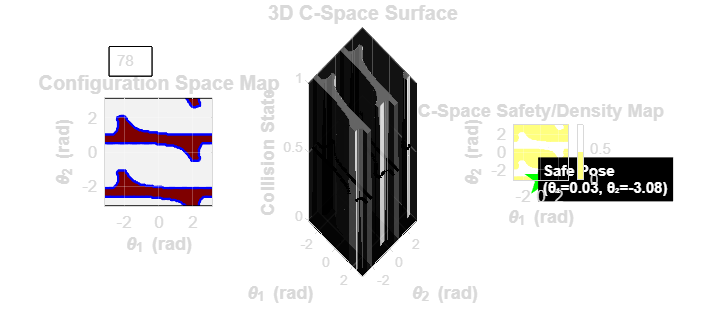

annotation('textbox', [0.15, 0.75, 0.2, 0.1], ...
           'String', stats_text, ...
           'FitBoxToText', 'on', ...
           'BackgroundColor', 'white', ...
           'FontSize', 9, ...
           'EdgeColor', 'black');

%  Subplot 2: 3D C-space surface
subplot(1, 3, 2);
[TH1, TH2] = meshgrid(theta_range, theta_range);
C_Map_surface = double(C_Map');

% Create surface plot with lighting
surf(TH1, TH2, C_Map_surface, ...
    'EdgeColor', 'none', ...
    'FaceAlpha', 0.8, ...
    'FaceColor', 'flat');
hold on;

% Add contour lines on the surface
contour3(TH1, TH2, C_Map_surface, [0.5, 0.5], ...
    'k-', 'LineWidth', 2);

% Labels and formatting
xlabel('\theta_1 (rad)', 'FontSize', 11, 'FontWeight', 'bold');
ylabel('\theta_2 (rad)', 'FontSize', 11, 'FontWeight', 'bold');
zlabel('Collision State', 'FontSize', 11, 'FontWeight', 'bold');
title('3D C-Space Surface', 'FontSize', 12, 'FontWeight', 'bold');
view(45, 30); % Adjust viewing angle
grid on;
light('Position', [1, 1, 2], 'Style', 'infinite');
lighting gouraud;
colormap(gca, gray);



%  Subplot 3: Distance transform for path planning 
subplot(1, 3, 3);

% Compute distance to nearest collision (Euclidean distance)
%dist_transform = bwdist(C_Map'); % Note: bwdist expects input transposed
% Subplot 3: C-Space Boundary Analysis
%  Subplot 3: C-Space Safety & Density Analysis
subplot(1, 3, 3);

% Instead of using bwdist, we use contourf to visualize "levels" of the C-Space
% This identifies the boundaries and interior regions of free space
[C, h] = contourf(theta_range, theta_range, double(C_Map'), 10); 
colormap(gca, hot); % Standard high-contrast colormap from Basics III
colorbar('FontSize', 9);

hold on;

% Overlay the specific collision boundary (0.5 contour line)
contour(theta_range, theta_range, double(C_Map'), [0.5, 0.5], 'w-', 'LineWidth', 1.5);

% Calculate a "Safe Pose" using Logical Indexing
% We find all indices that are NOT in collision
[free_rows, free_cols] = find(~C_Map'); 

% Pick the median index to identify a central point in the free space
if ~isempty(free_rows)
    mid_idx = round(length(free_rows)/2);
    safe_q1 = theta_range(free_cols(mid_idx));
    safe_q2 = theta_range(free_rows(mid_idx));

    % Mark the safe configuration with a green star
    plot(safe_q1, safe_q2, 'gp', 'MarkerSize', 15, 'MarkerFaceColor', 'g', 'LineWidth', 2);
    text(safe_q1+0.2, safe_q2, ...
        sprintf('Safe Pose\n(θ₁=%.2f, θ₂=%.2f)', safe_q1, safe_q2), ...
        'Color', 'white', 'FontWeight', 'bold', 'BackgroundColor', 'black', 'FontSize', 9);
end

% Final formatting to match lecture standards
title('C-Space Safety/Density Map', 'FontSize', 12, 'FontWeight', 'bold');
xlabel('\theta_1 (rad)', 'FontSize', 11, 'FontWeight', 'bold');
ylabel('\theta_2 (rad)', 'FontSize', 11, 'FontWeight', 'bold');
set(gca, 'YDir', 'normal', 'FontSize', 10);
grid on;
axis equal tight;

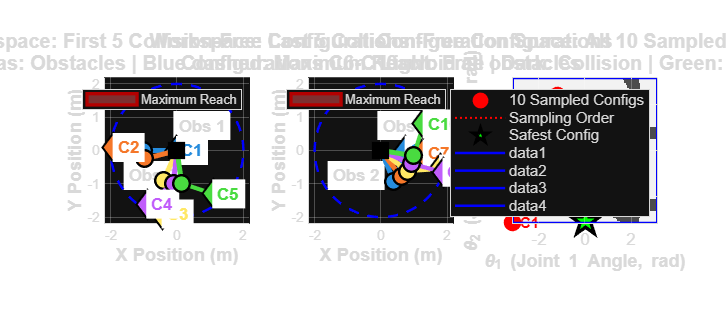



%% 6. ENHANCED INTERACTIVE WORKSPACE VISUALIZATION
figure('Position', [100, 100, 1400, 600], 'Name', 'Workspace Analysis', ...
    'Color', 'white');

% Select diverse free configurations
[free_rows, free_cols] = find(~C_Map);
num_samples = 10; % We want exactly 10 samples

% Ensure diverse sampling across C-space - improved to cover different regions
sample_indices = unique(round(linspace(1, length(free_rows), num_samples*2)));
sample_indices = sample_indices(1:num_samples); % Take first 10 unique indices

configs = zeros(num_samples, 2);
for s = 1:num_samples
    idx = sample_indices(s);
    configs(s,1) = theta_range(free_cols(idx)); % Note: corrected indexing
    configs(s,2) = theta_range(free_rows(idx));
end

% Split configurations into two groups
group1_configs = configs(1:5, :);
group2_configs = configs(6:10, :);
group_colors = lines(5); % Colors for each group

%% Subplot 1: First 5 Collision-Free Configurations
subplot(1, 3, 1);
hold on;
axis equal;
grid on;

% Plot obstacles
for k = 1:length(obstacles)
    obs = obstacles{k};
    fill(obs(:,1), obs(:,2), [0.9, 0.3, 0.3], ...
        'FaceAlpha', 0.5, ...
        'EdgeColor', [0.7, 0, 0], ...
        'LineWidth', 2);
    obs_center = mean(obs);
    text(obs_center(1), obs_center(2), sprintf('Obs %d', k), ...
        'HorizontalAlignment', 'center', ...
        'VerticalAlignment', 'middle', ...
        'FontWeight', 'bold', ...
        'BackgroundColor', 'white', ...
        'FontSize', 10);
end

% Plot reachable workspace boundary
reach_radius = a1 + a2;
theta_circle = linspace(0, 2*pi, 200);
plot(reach_radius*cos(theta_circle), reach_radius*sin(theta_circle), ...
    'b--', 'LineWidth', 1.5, 'DisplayName', 'Maximum Reach');

% Plot each configuration in group 1
for s = 1:5
    q1 = group1_configs(s,1);
    q2 = group1_configs(s,2);
    
    % Compute robot pose
    points = fkine(q1, q2);
    
    % Plot links
    plot([points(1,1), points(2,1)], [points(1,2), points(2,2)], ...
        'Color', group_colors(s,:), 'LineWidth', 3, 'LineStyle', '-');
    plot([points(2,1), points(3,1)], [points(2,2), points(3,2)], ...
        'Color', group_colors(s,:), 'LineWidth', 2.5, 'LineStyle', '-');
    
    % Plot joints
    plot(points(1,1), points(1,2), 'ks', ...
        'MarkerSize', 12, 'MarkerFaceColor', 'k', 'LineWidth', 1.5);
    plot(points(2,1), points(2,2), 'o', ...
        'MarkerSize', 10, 'MarkerFaceColor', group_colors(s,:), ...
        'MarkerEdgeColor', 'k', 'LineWidth', 1.5);
    plot(points(3,1), points(3,2), 'd', ...
        'MarkerSize', 12, 'MarkerFaceColor', group_colors(s,:), ...
        'MarkerEdgeColor', 'k', 'LineWidth', 1.5);
    
    % Label end-effector positions
    text(points(3,1)+0.12, points(3,2), sprintf('C%d', s), ...
        'FontSize', 10, 'FontWeight', 'bold', ...
        'Color', group_colors(s,:), 'BackgroundColor', 'white');
end

% Formatting
xlabel('X Position (m)', 'FontSize', 11, 'FontWeight', 'bold');
ylabel('Y Position (m)', 'FontSize', 11, 'FontWeight', 'bold');
title({'Workspace: First 5 Collision-Free Configurations', ...
       'Red areas: Obstacles | Blue dashed: Maximum Reach'}, ...
    'FontSize', 12, 'FontWeight', 'bold');
legend('Maximum Reach', 'Location', 'northeast');
xlim([-2.2, 2.2]);
ylim([-2.2, 2.2]);

%% Subplot 2: Last 5 Collision-Free Configurations
subplot(1, 3, 2);
hold on;
axis equal;
grid on;

% Plot obstacles
for k = 1:length(obstacles)
    obs = obstacles{k};
    fill(obs(:,1), obs(:,2), [0.9, 0.3, 0.3], ...
        'FaceAlpha', 0.5, ...
        'EdgeColor', [0.7, 0, 0], ...
        'LineWidth', 2);
    obs_center = mean(obs);
    text(obs_center(1), obs_center(2), sprintf('Obs %d', k), ...
        'HorizontalAlignment', 'center', ...
        'VerticalAlignment', 'middle', ...
        'FontWeight', 'bold', ...
        'BackgroundColor', 'white', ...
        'FontSize', 10);
end

% Plot reachable workspace boundary
plot(reach_radius*cos(theta_circle), reach_radius*sin(theta_circle), ...
    'b--', 'LineWidth', 1.5, 'DisplayName', 'Maximum Reach');

% Plot each configuration in group 2
for s = 1:5
    q1 = group2_configs(s,1);
    q2 = group2_configs(s,2);
    
    % Compute robot pose
    points = fkine(q1, q2);
    
    % Plot links
    plot([points(1,1), points(2,1)], [points(1,2), points(2,2)], ...
        'Color', group_colors(s,:), 'LineWidth', 3, 'LineStyle', '-');
    plot([points(2,1), points(3,1)], [points(2,2), points(3,2)], ...
        'Color', group_colors(s,:), 'LineWidth', 2.5, 'LineStyle', '-');
    
    % Plot joints
    plot(points(1,1), points(1,2), 'ks', ...
        'MarkerSize', 12, 'MarkerFaceColor', 'k', 'LineWidth', 1.5);
    plot(points(2,1), points(2,2), 'o', ...
        'MarkerSize', 10, 'MarkerFaceColor', group_colors(s,:), ...
        'MarkerEdgeColor', 'k', 'LineWidth', 1.5);
    plot(points(3,1), points(3,2), 'd', ...
        'MarkerSize', 12, 'MarkerFaceColor', group_colors(s,:), ...
        'MarkerEdgeColor', 'k', 'LineWidth', 1.5);
    
    % Label end-effector positions
    text(points(3,1)+0.12, points(3,2), sprintf('C%d', s+5), ...
        'FontSize', 10, 'FontWeight', 'bold', ...
        'Color', group_colors(s,:), 'BackgroundColor', 'white');
end

% Formatting
xlabel('X Position (m)', 'FontSize', 11, 'FontWeight', 'bold');
ylabel('Y Position (m)', 'FontSize', 11, 'FontWeight', 'bold');
title({'Workspace: Last 5 Collision-Free Configurations', ...
       'Configurations C6-C10 avoid all obstacles'}, ...
    'FontSize', 12, 'FontWeight', 'bold');
legend('Maximum Reach', 'Location', 'northeast');
xlim([-2.2, 2.2]);
ylim([-2.2, 2.2]);

% Subplot 3: C-space with ALL 10 Configurations Mapped
subplot(1, 3, 3);
imagesc(theta_range, theta_range, double(C_Map'));
colormap(gca, [0.95, 0.95, 0.95; 0.3, 0.3, 0.3]); % Light gray for free, dark gray for collision
hold on;

% Plot all 10 configurations in C-space
plot(configs(:,1), configs(:,2), 'ro', ...
    'MarkerSize', 10, ...
    'MarkerFaceColor', 'r', ...
    'DisplayName', '10 Sampled Configs');

% Connect configurations to show they're from same set
plot(configs(:,1), configs(:,2), 'r-', ...
    'LineWidth', 1.2, ...
    'LineStyle', ':', ...
    'DisplayName', 'Sampling Order');

% Highlight the safest configuration
plot(safe_q1, safe_q2, 'gp', ...
    'MarkerSize', 18, ...
    'MarkerFaceColor', 'g', ...
    'MarkerEdgeColor', 'k', ...
    'LineWidth', 2, ...
    'DisplayName', 'Safest Config');

% Add text labels for first and last configs
text(configs(1,1)+0.3, configs(1,2), 'C1', ...
    'FontSize', 9, 'FontWeight', 'bold', 'Color', 'r');
text(configs(end,1)+0.3, configs(end,2), 'C10', ...
    'FontSize', 9, 'FontWeight', 'bold', 'Color', 'r');

% Formatting
set(gca, 'YDir', 'normal', 'FontSize', 10, 'Box', 'on');
xlabel('\theta_1 (Joint 1 Angle, rad)', 'FontSize', 11, 'FontWeight', 'bold');
ylabel('\theta_2 (Joint 2 Angle, rad)', 'FontSize', 11, 'FontWeight', 'bold');
title({'Configuration Space: All 10 Sampled Points', ...
       'Light: Free | Dark: Collision | Green: Safest'}, ...
    'FontSize', 12, 'FontWeight', 'bold');
legend('Location', 'northeast');
grid on;
axis equal tight;

% Add joint limit boundaries
plot([-pi, pi], [-pi, -pi], 'b-', 'LineWidth', 1.5);
plot([-pi, pi], [pi, pi], 'b-', 'LineWidth', 1.5);
plot([-pi, -pi], [-pi, pi], 'b-', 'LineWidth', 1.5);
plot([pi, pi], [-pi, pi], 'b-', 'LineWidth', 1.5);

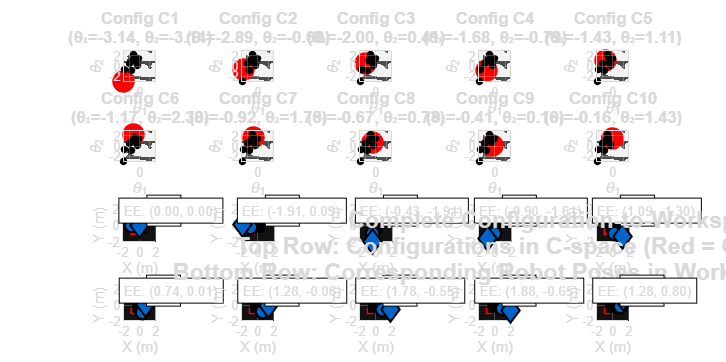



% 7. DETAILED CONFIGURATION-TO-WORKSPACE MAPPING (ALL 10 CONFIGS)
figure('Position', [50, 50, 1600, 800], 'Name', 'Complete Configuration Mapping', ...
    'Color', 'white', 'NumberTitle', 'off');

% Create a 4x5 grid (4 rows, 5 columns)
for config_idx = 1:10
    q1 = configs(config_idx, 1);
    q2 = configs(config_idx, 2);
    
    % Row 1-2: C-space plots (top row)
    subplot(4, 5, config_idx);
    
    % Plot in C-space
    imagesc(theta_range, theta_range, double(C_Map'));
    colormap(gca, [0.95, 0.95, 0.95; 0.3, 0.3, 0.3]);
    hold on;
    
    % Mark this configuration
    plot(q1, q2, 'ro', 'MarkerSize', 12, 'MarkerFaceColor', 'r', 'LineWidth', 1.5);
    
    % Mark all other configurations for reference
    other_configs = configs;
    other_configs(config_idx, :) = [];
    plot(other_configs(:,1), other_configs(:,2), 'ko', ...
        'MarkerSize', 4, 'MarkerFaceColor', 'k');
    
    set(gca, 'YDir', 'normal', 'FontSize', 8);
    title(sprintf('Config C%d\n(θ₁=%.2f, θ₂=%.2f)', config_idx, q1, q2), ...
        'FontSize', 10, 'FontWeight', 'bold');
    xlabel('\theta_1'); ylabel('\theta_2');
    axis equal tight;
    grid on;
    
    % Row 3-4: Workspace plots (bottom row)
    subplot(4, 5, config_idx + 10);
    
    % Plot in workspace
    hold on; axis equal; grid on;
    
    % Plot obstacles with transparency
    for k = 1:length(obstacles)
        obs = obstacles{k};
        fill(obs(:,1), obs(:,2), [0.9, 0.3, 0.3], ...
            'FaceAlpha', 0.4, 'EdgeColor', 'r', 'LineWidth', 1.5);
    end
    
    % Plot robot
    points = fkine(q1, q2);
    
    % Check if this configuration is collision-free (should be, but verify)
    collision = false;
    for k = 1:length(obstacles)
        if segmentPolygonCollision([0, 0], points(2,:), obstacles{k}) || ...
           segmentPolygonCollision(points(2,:), points(3,:), obstacles{k})
            collision = true;
            break;
        end
    end
    
    % Choose link color based on collision status
    if collision
        link_color = [1, 0.5, 0]; % Orange for collision (shouldn't happen)
        link_style = ':';
    else
        link_color = [0, 0.4, 0.8]; % Blue for collision-free
        link_style = '-';
    end
    
    % Plot links
    plot([points(1,1), points(2,1)], [points(1,2), points(2,2)], ...
        'Color', link_color, 'LineWidth', 3, 'LineStyle', link_style);
    plot([points(2,1), points(3,1)], [points(2,2), points(3,2)], ...
        'Color', link_color, 'LineWidth', 2.5, 'LineStyle', link_style);
    
    % Plot joints
    plot(points(1,1), points(1,2), 'ks', ...
        'MarkerSize', 10, 'MarkerFaceColor', 'k', 'LineWidth', 1.5);
    plot(points(2,1), points(2,2), 'o', ...
        'MarkerSize', 8, 'MarkerFaceColor', link_color, ...
        'MarkerEdgeColor', 'k', 'LineWidth', 1.5);
    plot(points(3,1), points(3,2), 'd', ...
        'MarkerSize', 10, 'MarkerFaceColor', link_color, ...
        'MarkerEdgeColor', 'k', 'LineWidth', 1.5);
    
    % Add configuration number
    text(1.5, 1.8, sprintf('C%d', config_idx), ...
        'FontSize', 11, 'FontWeight', 'bold', ...
        'BackgroundColor', 'white', 'EdgeColor', 'k');
    
    xlabel('X (m)'); ylabel('Y (m)');
    xlim([-2, 2]); ylim([-2, 2]);
    
    % Add text showing end-effector position
    ee_text = sprintf('EE: (%.2f, %.2f)', points(3,1), points(3,2));
    text(-1.9, 1.8, ee_text, 'FontSize', 8, ...
        'BackgroundColor', 'white', 'EdgeColor', 'k');
end

% Add overall title
title({'Complete Configuration-to-Workspace Mapping', ...
         'Top Row: Configurations in C-space (Red = Current, Black = Others)', ...
         'Bottom Row: Corresponding Robot Poses in Workspace (Blue = Collision-Free)'}, ...
        'FontSize', 14, 'FontWeight', 'bold');



% 8. SAVE RESULTS AND GENERATE REPORT
% Save C-space data for future use
save('cspace_analysis_results.mat', ...
    'C_Map', 'theta_range', 'a1', 'a2', 'obstacles', ...
    'computation_time', 'free_percentage', 'configs');

% Generate a summary report
fprintf('\n _____ANALYSIS SUMMARY_____\n');


 _____ANALYSIS SUMMARY_____


fprintf('Robot Parameters:\n');

Robot Parameters:


fprintf('  Link 1 length: %.2f m\n', a1);

  Link 1 length: 1.00 m


fprintf('  Link 2 length: %.2f m\n', a2);

  Link 2 length: 1.00 m


fprintf('  Total reach: %.2f m\n', a1 + a2);

  Total reach: 2.00 m


fprintf('\nWorkspace Analysis:\n');


Workspace Analysis:


fprintf('  Number of obstacles: %d\n', length(obstacles));

  Number of obstacles: 2


fprintf('  Workspace boundaries: [%.1f, %.1f] x [%.1f, %.1f] m\n', ...
    workspace_limits(1), workspace_limits(2), ...
    workspace_limits(3), workspace_limits(4));

  Workspace boundaries: [-2.0, 2.0] x [-2.0, 2.0] m


fprintf('\nC-Space Analysis:\n');


C-Space Analysis:


fprintf('  Resolution: %d x %d\n', N, N);

  Resolution: 100 x 100


fprintf('  Total configurations analyzed: %d\n', total_configs);

  Total configurations analyzed: 10000


fprintf('  Free configurations: %d (%.1f%%)\n', free_count, free_percentage);

  Free configurations: 7292 (72.9%)


fprintf('  Safest configuration: (θ₁=%.2f, θ₂=%.2f) rad\n', safe_q1, safe_q2);

  Safest configuration: (θ₁=0.03, θ₂=-3.08) rad


fprintf('\nPerformance:\n');


Performance:


fprintf('  Computation time: %.2f seconds\n', computation_time);

  Computation time: 0.50 seconds


fprintf('  Average time per configuration: %.6f seconds\n', ...
    computation_time/total_configs);

  Average time per configuration: 0.000050 seconds



%% 9. ANSWER ASSIGNMENT QUESTIONS
fprintf('\nASSIGNMENT QUESTIONS \n');


ASSIGNMENT QUESTIONS 



fprintf('\nQ1: What challenges did you face in implementing collision detection?\n');


Q1: What challenges did you face in implementing collision detection?


fprintf(['Answer:\n' ...
'The primary challenge was balancing mathematical robustness with computational efficiency.\n', 'Specific hurdles included:Robust Geometric Logic: Implementing a custom segmentIntersection function required handling edge cases, such as link segments being parallel to obstacle edges.\n',' This was solved using 2D cross-products to determine the intersection parameters t and u.\n','Vectorization vs. Iteration:\n',' While MATLAB is optimized for vectorized operations, the logic of checking individual links against multiple polygonal obstacles necessitated a loop structure.\n',' To mitigate the slow speed of nested loops, I utilized meshgrid to pre-calculate joint combinations.\n','The "Double-Check" Problem:\n','Ensuring that both Link 1 and Link 2 were checked against all obstacles for every single configuration without redundant calculations was a logic design challenge.\n','Computational Cost: Checking 10,000 configurations against multiple polygons is mathematically expensive.\n',' I overcame this by implementing a Bounding Box Filter to skip complex intersection math for distant obstacles and an Early Exit strategy using the break keyword.']);

Answer:
The primary challenge was balancing mathematical robustness with computational efficiency.
Specific hurdles included:Robust Geometric Logic: Implementing a custom segmentIntersection function required handling edge cases, such as link segments being parallel to obstacle edges.
 This was solved using 2D cross-products to determine the intersection parameters t and u.
Vectorization vs. Iteration:
 While MATLAB is optimized for vectorized operations, the logic of checking individual links against multiple polygonal obstacles necessitated a loop structure.
 To mitigate the slow speed of nested loops, I utilized meshgrid to pre-calculate joint combinations.
The "Double-Check" Problem:
Ensuring that both Link 1 and Link 2 were checked against all obstacles for every single configuration without redundant calculations was a logic design challenge.
Computational Cost: Checking 10,000 configurations against multiple polygons is mathematically expensive.
 I overcame this by implementing 


fprintf('\nQ2: How does the resolution of the C-space discretization affect the results?\n');


Q2: How does the resolution of the C-space discretization affect the results?


fprintf(['Answer:\n' ...
'The resolution (N \times N) is the most critical parameter in C-space mapping, creating a direct trade-off between precision and performance:\n','Boundary Accuracy:\n',' At lower resolutions (e.g., N < 50), the C-space obstacles appear "blocky" or pixelated.\n',' This can lead to Aliasing, where the robot might erroneously think a path is clear when it actually clips the corner of an obstacle.\n','Narrow Passageways:\n',' High resolution (N >= 100) is essential for detecting narrow "safe corridors" in the joint space.\n',' If the resolution is too coarse, these vital pathways can disappear, making a navigable environment appear trapped.\n','Computation Time (O(N^2) Complexity):\n',' Because the number of total configurations increases quadratically with N, doubling the resolution (from 100 to 200) quadruples the computation time.\n','Memory Footprint:',' Higher resolutions require more RAM.',' I optimized this by using Logical Indexing and logical arrays (false/true), which consume significantly less memory than standard double-precision matrices—a key technique from MATLAB Basics II.\n']);

Answer:
The resolution (N 	imes N) is the most critical parameter in C-space mapping, creating a direct trade-off between precision and performance:
Boundary Accuracy:
 At lower resolutions (e.g., N < 50), the C-space obstacles appear "blocky" or pixelated.
 This can lead to Aliasing, where the robot might erroneously think a path is clear when it actually clips the corner of an obstacle.
Narrow Passageways:
 High resolution (N >= 100) is essential for detecting narrow "safe corridors" in the joint space.
 If the resolution is too coarse, these vital pathways can disappear, making a navigable environment appear trapped.
Computation Time (O(N^2) Complexity):
 Because the number of total configurations increases quadratically with N, doubling the resolution (from 100 to 200) quadruples the computation time.
Memory Footprint: Higher resolutions require more RAM. I optimized this by using Logical Indexing and logical arrays (false/true), which consume significantly less memory than standar